T = readtable("20khz2.csv")

T = 16777216×2 table
    Time_s_    Channel1_V_
    _______    ___________

    -419.43      0.11359  
    -419.43      0.11325  
    -419.43      0.11325  
    -419.43      0.11359  
    -419.43      0.11325  
    -419.43      0.11325  
    -419.43      0.11392  
    -419.43      0.11325  
    -419.43      0.11325  
    -419.43      0.11359  
    -419.43      0.11325  
    -419.43      0.11325  
    -419.43      0.11392  
    -419.43      0.11325  
    -419.43      0.11291  
    -419.43      0.11392  


S=T{:,"Channel1_V_"}'

S =     0.1136    0.1132    0.1132    0.1136    0.1132    0.1132    0.1139    0.1132    0.1132    0.1136    0.1132    0.1132    0.1139    0.1132    0.1129    0.1139    0.1132    0.1132    0.1139    0.1132    0.1132    0.1139    0.1132    0.1132    0.1136    0.1132    0.1129    0.1136    0.1132    0.1129    0.1139    0.1136    0.1132    0.1139    0.1136    0.1129    0.1139    0.1136    0.1129    0.1139    0.1136    0.1129    0.1139    0.1136    0.1129    0.1136    0.1136    0.1129    0.1139    0.1136


t=T{:,"Time_s_"}'

t =  -419.4304 -419.4303 -419.4303 -419.4303 -419.4302 -419.4302 -419.4301 -419.4300 -419.4300 -419.4300 -419.4299 -419.4298 -419.4298 -419.4298 -419.4297 -419.4296 -419.4296 -419.4296 -419.4295 -419.4294 -419.4294 -419.4293 -419.4293 -419.4293 -419.4292 -419.4291 -419.4291 -419.4291 -419.4290 -419.4289 -419.4289 -419.4289 -419.4288 -419.4287 -419.4287 -419.4287 -419.4286 -419.4285 -419.4285 -419.4284 -419.4284 -419.4284 -419.4283 -419.4282 -419.4282 -419.4282 -419.4281 -419.4280 -419.4280 -419.4280


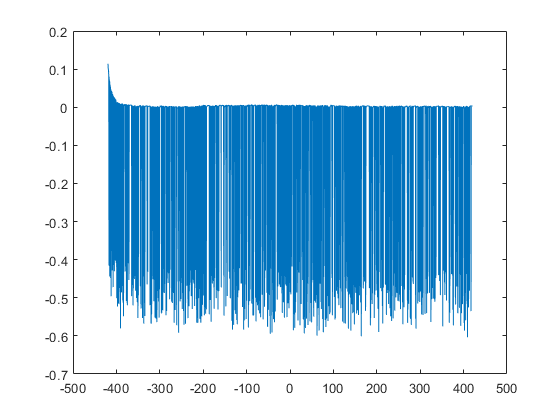


plot(t,S)

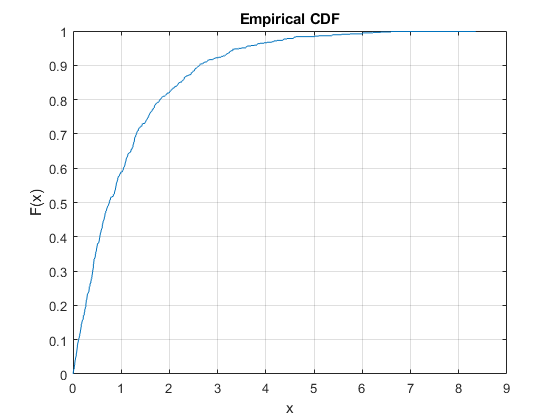

spikes = diff(S<-0.1)>0.5;
detection_times = t(spikes);
random_intervals = diff(detection_times);
cdfplot(random_intervals) %normplot

[muhat,muci] = expfit(random_intervals)

muhat = 1.1412

muci =     1.0627
    1.2286


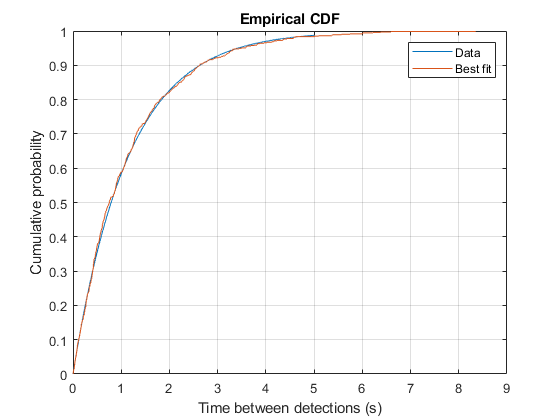

x=0:0.001:5;
y = expcdf(x,muhat);
figure
plot(x,y)
hold on
cdfplot(random_intervals)
legend("Data", "Best fit")
xlabel("Time between detections (s)")
ylabel("Cumulative probability")
hold off

plot(x, exppdf(x,muhat))
title("Probability distribution")
xlabel("Time between detections (s)")
ylabel("Probability density")
legend("lambda=1.1412")

parts = 8
intervals = [0];
for i=1/parts:1/parts:1
    [~, idx] = min((y-i).^2);
    intervals = [intervals x(idx)];
end
p=zeros(1, length(random_intervals));
for i=2:parts+1
    p = p+(intervals(i-1)<=random_intervals & random_intervals<intervals(i))*(i-2)/(parts-1);
end
plot(sort(p))

parts=8
r = rand(1, length(p))
p=zeros(1, length(random_intervals));
for i=2:parts+1
    p = p+((1/parts*(i-2))<=r & r<((i-1)*1/parts))*(i-2)/(parts-1);
end
plot(sort(p))

edges = linspace(0,1,parts+1); % edges of the bins
E = length(p)/parts*ones(parts,1); % expected value (equal for uniform dist)

[h,pp,stats] = chi2gof(p,'Expected',E,'Edges',edges)

gaussian_random = norminv(expcdf(random_intervals, muhat));

x_norm = [-3:.1:3];
y_norm = normcdf(x_norm,0,1);
figure
cdfplot(gaussian_random)
hold on
plot(x_norm,y_norm)
legend("Transformed data", "Gaussian distribution","Location","best")
xlabel("Generated nandom number")
ylabel("Cumulative probability")
hold off

[h,pp,stats] = chi2gof(gaussian_random)

length(gaussian_random)

regexprep(num2str(gaussian_random, 15),'\s+',',')

716/8

x_norm = [-3:.1:3];
y_norm = normpdf(x_norm,0,1);
plot(x_norm,y_norm)
title("Probability distribution")
xlabel("Generated nandom number")
ylabel("Probability density")

ans =     0.1456    0.1526   -0.4908    0.1173   -0.3105   -1.4906   -0.3767   -0.4311    1.2380   -1.4786    0.6665   -0.4983    0.4490    0.7742    1.1110    0.9022   -0.0812   -0.8917   -0.6344    0.6338   -0.3904    0.0756   -0.0115   -0.4984    0.9092   -2.0171   -2.3110    0.1036   -0.2461    0.1147   -1.5261    0.6633   -0.1480   -0.0139    1.0406   -0.4545   -0.3043   -0.5318   -0.4127   -1.3503   -0.7535    1.5998    1.0694   -0.1135    0.0737    0.0855   -0.4450    0.9588    0.5634   -0.6165


load ev.mat

i=3

i = 3

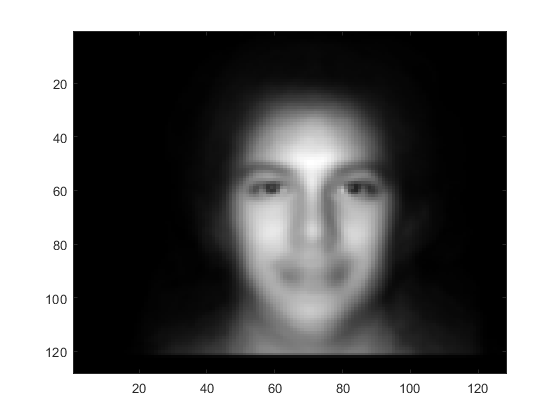

    v=gaussian_random(1+i*99:(i+1)*99)';
    i = eigenfaces'*v + mean_face';
    imagesc(reshape(i, 128, 128)'); colormap(gray(256));